clear all
KR_params

$$ans = \left(\begin{array}{ccc} 2.4167e+03 & 0 & 0\\ 0 & 2.2375e+03 & 0\\ 0 & 0 & 2.1792e+03 \end{array}\right)$$


J

J = 	1.0e+03 *

    2.4167         0         0
         0    2.2375         0
         0         0    2.1792


M=[2 2 2]

M =      2     2     2


t=linspace(0,20,100e3);

omega0=[-0.15; 0.1; -0.3]

omega0 =    -0.1500
    0.1000
   -0.3000


A0=eye(3)

A0 =      1     0     0
     0     1     0
     0     0     1



x0=[omega0; reshape(A0,[9 1])]

x0 =    -0.1500
    0.1000
   -0.3000
    1.0000
         0
         0
         0
    1.0000
         0
         0


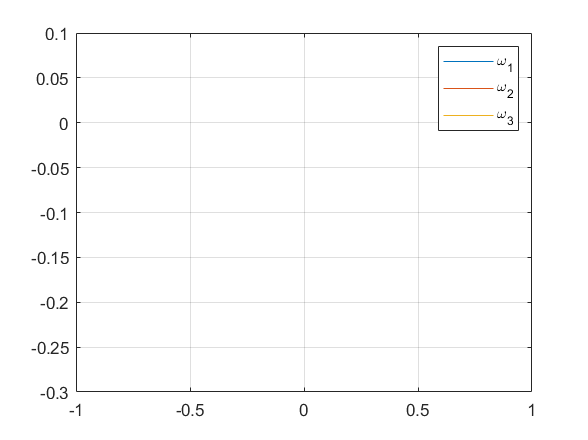



[t,y]= ode45(@(t,x) next(x(1:3),reshape(x(4:end),[3 3]),J,M),t,x0 );
w=y(:,1:3);
a=y(:,4:end);
figure
plot(t,w)
grid on
legend("\omega_1","\omega_2","\omega_3")

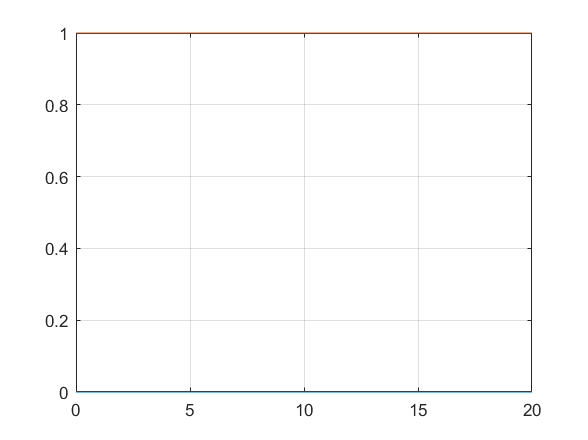


figure
plot(t,a)
grid on

% 
% syms a [3,3] real
% syms da [3,3] real
% syms omega [3,1] real
% 
% a
% Omega = [
%     0 -omega3 omega2
%     omega3 0 -omega1
%     -omega2 omega1 0
%     ]
% 
% dA= -Omega*a


Уравнения Эйлера и Пуассона

function y=next(omega,A,J,M)

dw=zeros(3,1);

dw(1)=( (J(2)-J(3)) * omega(2) * omega(3) - M(1) * sign(omega(1)) ) / J(1);
dw(2)=( (J(3)-J(1)) * omega(3) * omega(1) - M(2) * sign(omega(2)) ) / J(2);
dw(3)=( (J(1)-J(2)) * omega(1) * omega(2) - M(3) * sign(omega(3)) ) / J(3);

Omega = [
    0 -omega(3) omega(2)
    omega(3) 0 -omega(1)
    -omega(2) omega(1) 0
    ];

dA=-Omega*A;
dA=zeros(9,1);
y=[dw;reshape(dA,[9 1])];
end